# Approximating Higher Order Derivatives

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code loads and plots the space shuttle data from NASA. 

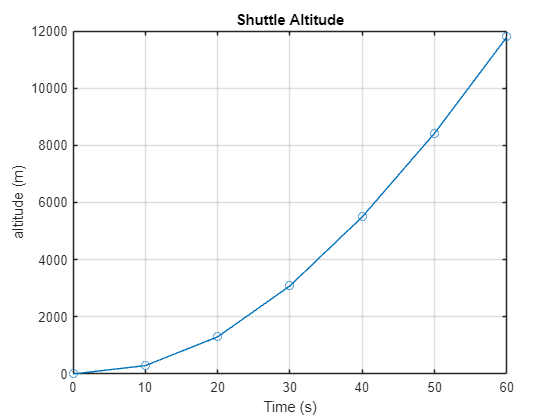

timeFromNASA = 0:10:60;
heightFromNASA = [2.2 293 1300 3085 5500 8428 11796];

plot(timeFromNASA,heightFromNASA,"o-")
grid on
title("Shuttle Altitude")
xlabel("Time (s)")
ylabel("altitude (m)")

## Task 1

In a previous chapter, you approximated the first derivative of position (also known as the velocity) of a launched shuttle.

*v*=*d**h/d**t*

But why stop there? You can approximate higher-order derivatives of position, too!

dt = 10;

## Task 2

The `diff` function takes the difference between successive elements in an array `A`. 

`dA` `=` `diff``(``A``)`

dh = diff(heightFromNASA);

## Task 3

v = dh/dt;

## Task 4

You can display functions in bar graphs using the `bar` function.

`bar``(``y``)`

You can also label the y-axis using the `ylabel` function. 

`ylabel``(``"text"``)`

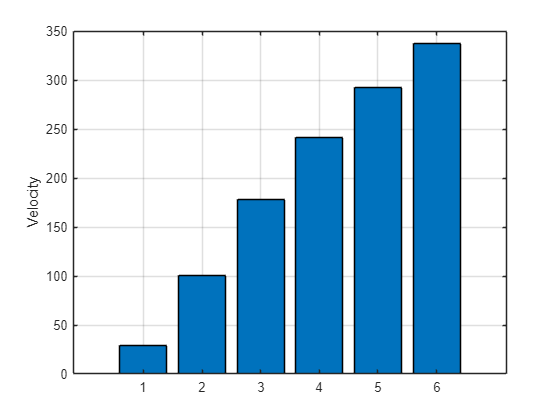

bar(v)
grid on
ylabel("Velocity")

## Task 5

As you can see from the bar  graph of velocity, the velocity of the shuttle is increasing with time! Let's repeat the process and find the acceleration of the shuttle, which is the derivative of velocity.

*a*=*d**v**d**t*

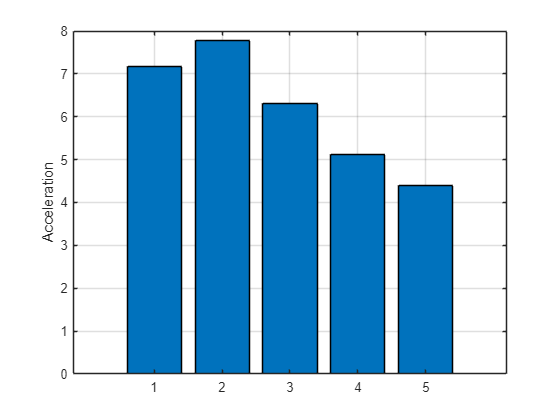

dv = diff(v);
a = dv/dt;
bar(a)
grid on
ylabel("Acceleration")

## Task 6

Velocity and acceleration are the first and second derivatives of position (or height in this example). However, in this example acceleration is also a function of time, which means that you can take the derivative of it, too! 

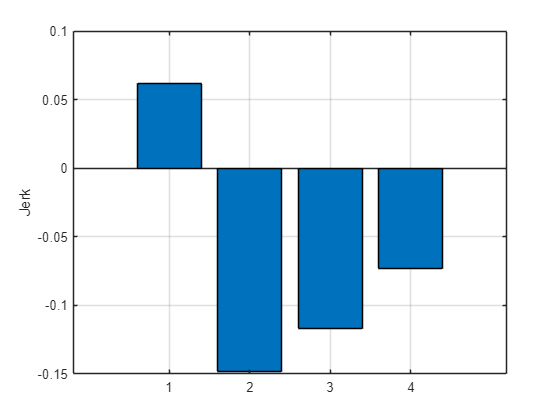

da = diff(a);
J = da/dt;
bar(J)
grid on
ylabel("Jerk")